clear all
close all 
clc

e = 1.602176*10^-19

e = 1.6022e-19

m = 9.1*10^-31

m = 9.1000e-31

kb = 1.38*10^-23

kb = 1.3800e-23

e0 = 8.85*10^-12

e0 = 8.8500e-12

h = 6.63*10^-34

h = 6.6300e-34

H = h/(2*pi)

H = 1.0552e-34

c = 3*10^6

c = 3000000

a0 = (4*pi*e0)/m * (H/e)^2

a0 = 5.3010e-11


E0 = -(m*e^4)/(8*(e0*h)^2)

E0 = -2.1771e-18


sprintf('Le rayon fondamental est %2f \n',a0*1e10)

ans = Le rayon fondamental est 0.530101 


sprintf('L''Energie fondamentale est %2f \n',E0/e)

ans = L'Energie fondamentale est -13.588405 


n = [1:4]

n =      1     2     3     4



rayon = a0*(n.^2)

rayon =    1.0e-09 *

    0.0530    0.2120    0.4771    0.8482



En = E0./(n.^2)

En =    1.0e-17 *

   -0.2177   -0.0544   -0.0242   -0.0136



E41 = En(4)-En(1)

E41 = 2.0410e-18

nu41 = E41/h

nu41 = 3.0785e+15

lambda41 = c/nu41

lambda41 = 9.7451e-10

sprintf('L''Energie necessaire pour descendre de E4 à E1 est %2f \n',lambda41*10)

ans = L'Energie necessaire pour descendre de E4 à E1 est 0.000000 


%Madelung : 1s² 2s² 2p^6 3s² 3p^6 4s² 3d^10 4p^1
%Le gallium est composée de 31 électrons, donc on a 8 niveaux énergétiques

b = [0:0.01:10]

b =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


na0 = a0.*b

na0 =    1.0e-10 *

         0    0.0053    0.0106    0.0159    0.0212    0.0265    0.0318    0.0371    0.0424    0.0477    0.0530    0.0583    0.0636    0.0689    0.0742    0.0795    0.0848    0.0901    0.0954    0.1007    0.1060    0.1113    0.1166    0.1219    0.1272    0.1325    0.1378    0.1431    0.1484    0.1537    0.1590    0.1643    0.1696    0.1749    0.1802    0.1855    0.1908    0.1961    0.2014    0.2067    0.2120    0.2173    0.2226    0.2279    0.2332    0.2385    0.2438    0.2491    0.2544    0.2597



R10 = (2/sqrt(a0^3)).*exp(-na0/(2*a0))

R10 =    1.0e+15 *

    5.1819    5.1561    5.1304    5.1048    5.0793    5.0540    5.0288    5.0037    4.9787    4.9539    4.9292    4.9046    4.8802    4.8558    4.8316    4.8075    4.7835    4.7597    4.7359    4.7123    4.6888    4.6654    4.6422    4.6190    4.5960    4.5730    4.5502    4.5275    4.5050    4.4825    4.4601    4.4379    4.4158    4.3937    4.3718    4.3500    4.3283    4.3067    4.2852    4.2639    4.2426    4.2215    4.2004    4.1794    4.1586    4.1379    4.1172    4.0967    4.0763    4.0559


R20 = (1/sqrt(2*a0^3)).*(1-(na0/(2*a0))).*exp(-na0/(2*a0))

R20 =    1.0e+15 *

    1.8321    1.8138    1.7957    1.7777    1.7599    1.7422    1.7246    1.7072    1.6898    1.6727    1.6556    1.6387    1.6219    1.6052    1.5887    1.5722    1.5559    1.5398    1.5237    1.5078    1.4920    1.4763    1.4607    1.4453    1.4299    1.4147    1.3996    1.3846    1.3698    1.3550    1.3404    1.3258    1.3114    1.2971    1.2829    1.2688    1.2548    1.2410    1.2272    1.2135    1.2000    1.1865    1.1732    1.1600    1.1468    1.1338    1.1209    1.1080    1.0953    1.0827


R21 = (na0/(2*sqrt(6*a0^3)*a0)).*exp(-na0/(2*a0))

R21 =    1.0e+14 *

         0    0.0526    0.1047    0.1563    0.2074    0.2579    0.3079    0.3575    0.4065    0.4550    0.5031    0.5506    0.5977    0.6443    0.6904    0.7360    0.7811    0.8258    0.8700    0.9138    0.9571    0.9999    1.0423    1.0843    1.1258    1.1668    1.2075    1.2476    1.2874    1.3267    1.3656    1.4041    1.4422    1.4798    1.5171    1.5539    1.5903    1.6263    1.6620    1.6972    1.7320    1.7665    1.8005    1.8342    1.8675    1.9004    1.9330    1.9651    1.9969    2.0284


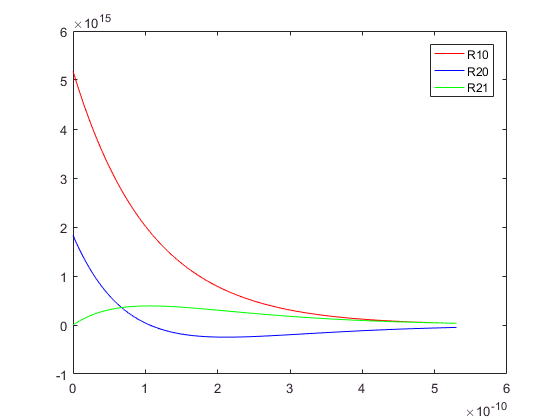


plot(na0,R10,'r')
hold on
plot(na0,R20,'b')
hold on
plot(na0,R21,'g')

legend('R10', 'R20', 'R21')

%Coordonnées polaires

figure
phi = [0:0.01:2*pi]

phi =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



Y00 = sqrt(1/(4*pi))

Y00 = 0.2821

Y11 = cos(phi)*(1/2)*sqrt(3/pi)

Y11 =     0.4886    0.4886    0.4885    0.4884    0.4882    0.4880    0.4877    0.4874    0.4870    0.4866    0.4862    0.4856    0.4851    0.4845    0.4838    0.4831    0.4824    0.4816    0.4807    0.4798    0.4789    0.4779    0.4768    0.4757    0.4746    0.4734    0.4722    0.4709    0.4696    0.4682    0.4668    0.4653    0.4638    0.4622    0.4606    0.4590    0.4573    0.4555    0.4537    0.4519    0.4500    0.4481    0.4461    0.4441    0.4421    0.4400    0.4378    0.4356    0.4334    0.4311


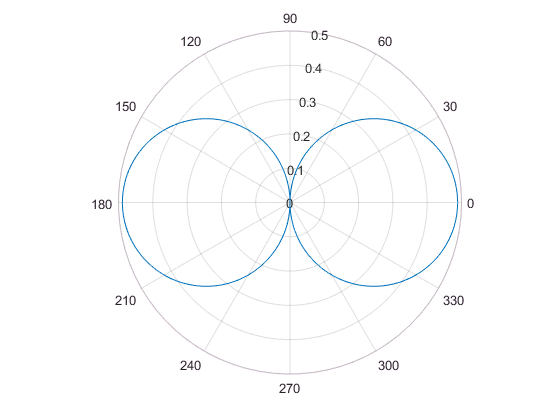


polarplot(phi,abs(Y11))

%Probabilité présence dans une orbite
figure

P1s = 4*pi*na0.^2.*abs(R10*Y00).^2

P1s =    1.0e+10 *

         0    0.0007    0.0030    0.0066    0.0116    0.0179    0.0256    0.0345    0.0446    0.0559    0.0683    0.0818    0.0964    0.1120    0.1286    0.1461    0.1646    0.1840    0.2042    0.2253    0.2471    0.2697    0.2931    0.3172    0.3419    0.3673    0.3933    0.4199    0.4471    0.4748    0.5031    0.5319    0.5611    0.5908    0.6209    0.6514    0.6823    0.7135    0.7451    0.7771    0.8093    0.8418    0.8746    0.9076    0.9408    0.9743    1.0080    1.0418    1.0758    1.1099


P2s = 4*pi*na0.^2.*abs(R20*Y00).^2

P2s =    1.0e+08 *

         0    0.0092    0.0362    0.0799    0.1393    0.2132    0.3009    0.4013    0.5136    0.6368    0.7702    0.9130    1.0644    1.2237    1.3901    1.5629    1.7416    1.9254    2.1138    2.3062    2.5021    2.7008    2.9020    3.1050    3.3095    3.5151    3.7212    3.9275    4.1335    4.3390    4.5436    4.7470    4.9488    5.1487    5.3464    5.5418    5.7345    5.9244    6.1111    6.2944    6.4743    6.6505    6.8228    6.9910    7.1551    7.3149    7.4702    7.6210    7.7671    7.9085


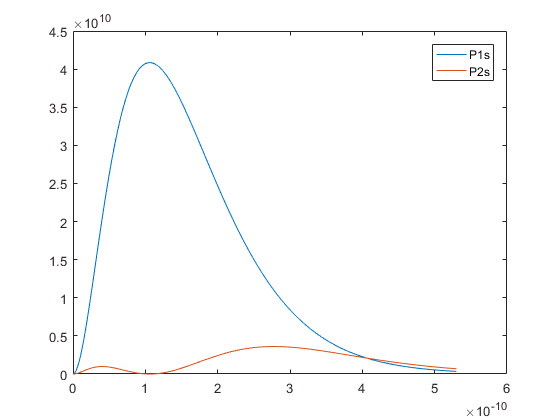


plot(na0,P1s,na0,P2s)
legend('P1s','P2s')

clear all
close all
clc

All functions in a script must be closed with an 'end'.



%% Préliminaires :représentation d'une parabole en coordonnées cartésiennes
%Maillage 1D
x=linspace(-1,1,10);
y=linspace(-1,1,10);
%Maillage 2D
[XX,YY]=meshgrid(x,y);
%Représentation de la sphère
ZZ=XX.^2+YY.^2;

figure
surf(XX,YY,ZZ,'linestyle','none');
xlabel('x')
ylabel('y')
zlabel('z')
colorbar




%% Fonctions angulaires

%Angles
theta=linspace(0,pi,1200);
dtheta=theta(2)-theta(1);
phi=linspace(0,2*pi,600);
%Maillage 2D
[Mtheta,Mphi]=meshgrid(theta,phi);
 
% Choix de l'orbitale angulaire Ã  reprÃ©senter
l=3;
m=2;

% AngularFunction
DP=AngularFunction(Mtheta,Mphi,l,m);
 
%Passsage coordonnées cartésiennes
xT=DP.*sin(Mtheta).*cos(Mphi);
yT=DP.*sin(Mtheta).*sin(Mphi);
zT=DP.*cos(Mtheta);
 
%représentation
figure(2)
mesh(xT,yT,zT)
xlabel('x')
ylabel('y')
zlabel('z')
colorbar
title('Fonction angulaire')
